## Use function "FindTraceInt" to get the intensity values

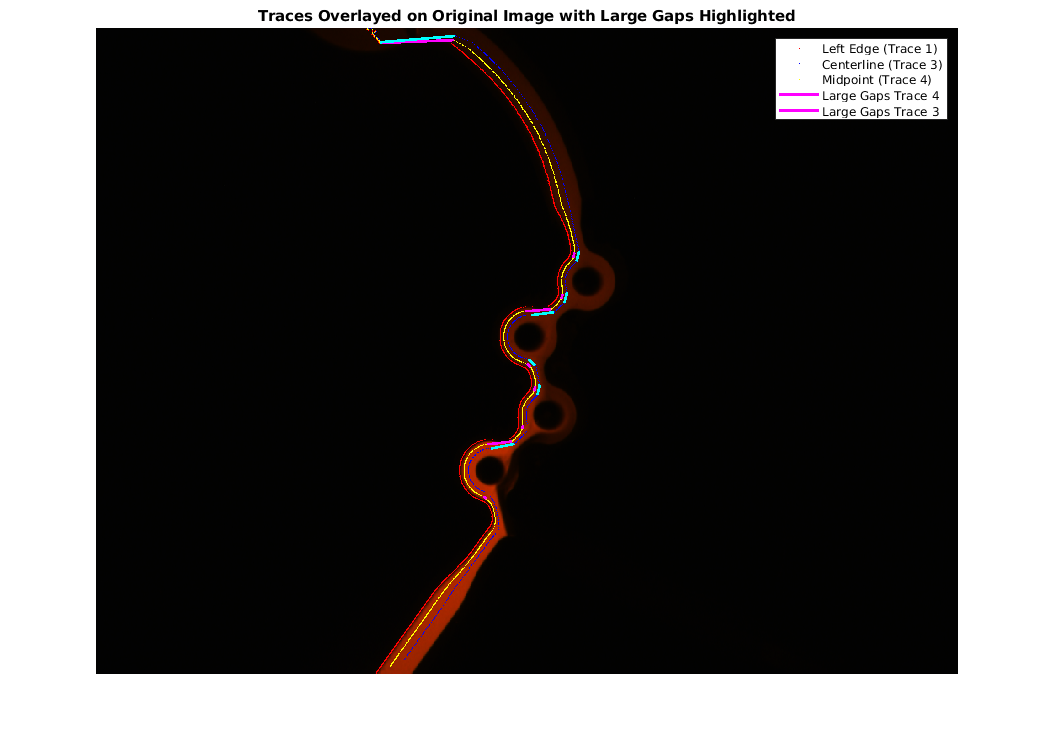

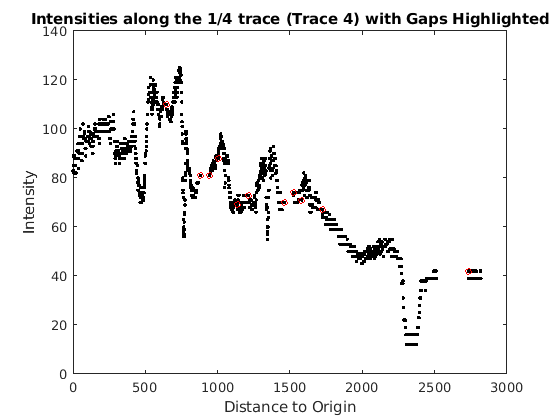

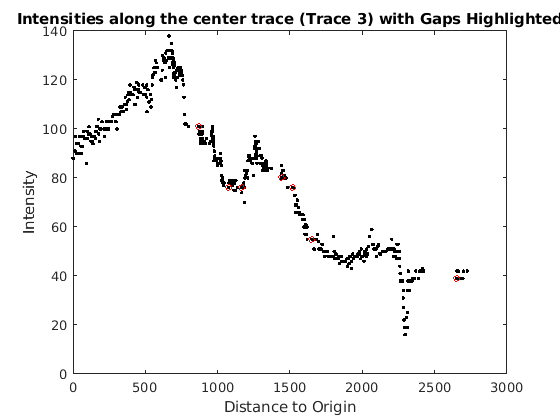

FindTraceInt('Mixing.tif');

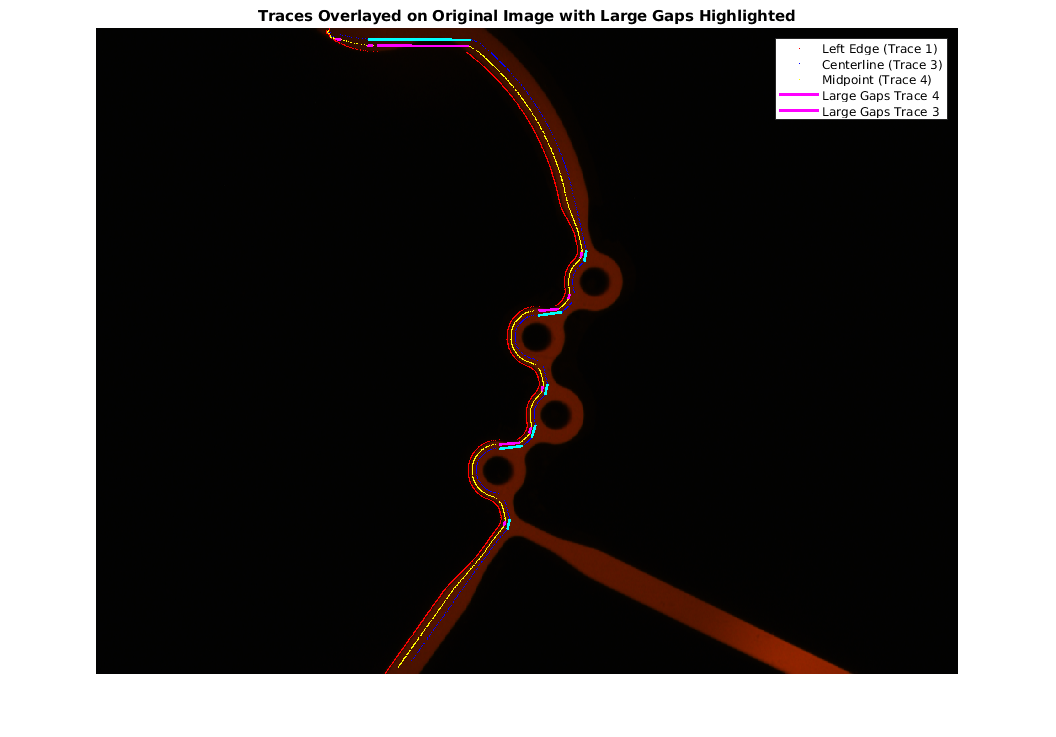

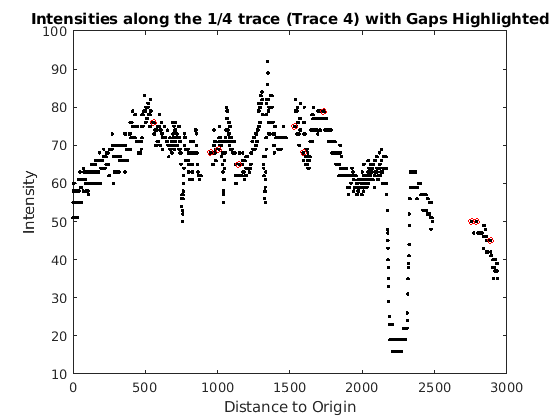

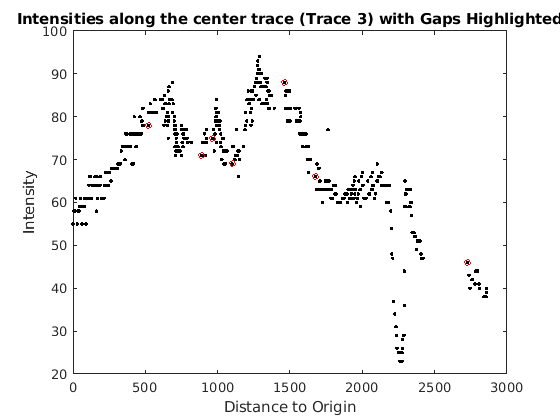

FindTraceInt('Dilution1.tif');

## Define a function to find the intensity along certain trace

function FindTraceInt(inputFileName)
    % Read the image
    img = imread(inputFileName);

    % Convert to grayscale
    grayImg = rgb2gray(img);

    % Enhance contrast using adaptive histogram equalization
    enhancedImg = adapthisteq(grayImg);

    % Apply a median filter to reduce noise
    filteredImg = medfilt2(enhancedImg, [3 3]);

    % Binarize the image
    binaryImg = imbinarize(filteredImg);

    % Remove small objects and fill gaps
    cleanedImg = bwareaopen(binaryImg, 50);
    se = strel('disk', 3); % Adjust size based on the typical gap length
    closedImg = imclose(cleanedImg, se);
    dilatedImg = imdilate(closedImg, se); % Further dilate to fill gaps

    % Detect edges
    edges = edge(dilatedImg, 'Sobel', [], 'vertical');

    % Initialize arrays to hold the left edge coordinates (Trace 1)
    leftEdgeX = [];
    leftEdgeY = [];

    % Loop through each row to find the first non-zero pixel (leftmost edge)
    for row = 1:size(edges, 1)
        col = find(edges(row, :), 1, 'first');
        if ~isempty(col)
            leftEdgeX = [leftEdgeX; col];
            leftEdgeY = [leftEdgeY; row];
        end
    end

    % Extract the skeleton (Trace 2)
    skeletonImg = bwskel(cleanedImg);

    % Find the coordinates of the skeleton
    [skeletonY, skeletonX] = find(skeletonImg);

    % Sort the coordinates by y
    [~, sortedIdx] = sort(skeletonY);
    skeletonX = skeletonX(sortedIdx);
    skeletonY = skeletonY(sortedIdx);

    % Create Trace 3 by finding the nearest point on the centerline for each point on the left edge
    trace3X = zeros(size(leftEdgeX));
    trace3Y = leftEdgeY;
    for i = 1:length(leftEdgeY)
        % Calculate distances to all points on the skeleton
        distances = sqrt((skeletonY - leftEdgeY(i)).^2 + (skeletonX - leftEdgeX(i)).^2);
        [~, nearestIdx] = min(distances);
        trace3X(i) = skeletonX(nearestIdx);
        trace3Y(i) = skeletonY(nearestIdx);
    end

### ***Change point1: Choose different percentile of the trace***

    % Create Trace 4 as the midpoint between Trace 1 and Trace 3
    trace4X = (leftEdgeX*5 + trace3X*5) / 10;
    trace4Y = (leftEdgeY*5 + trace3Y*5) / 10;
   

### ***End of change point 1***

    % Ensure Trace 4 has unique Y values by keeping the smallest X for each Y
    [uniqueTrace4Y, uniqueIdx] = unique(trace4Y, 'stable');
    uniqueTrace4X = trace4X(uniqueIdx);

    % Set the point on Trace 4 with the largest Y value as the origin
    [~, originIdx] = max(uniqueTrace4Y);
    originX = uniqueTrace4X(originIdx);
    originY = uniqueTrace4Y(originIdx);

    % Calculate the cumulative distance along Trace 4 from the largest Y
    distances4 = sqrt(diff(uniqueTrace4X).^2 + diff(uniqueTrace4Y).^2);
    cumulativeDistances4 = [0; cumsum(distances4)];

    % Reverse the cumulative distances to start from the point with the largest Y
    cumulativeDistances4 = cumulativeDistances4(end) - cumulativeDistances4;

    % Extract the intensities along the midpoint trace (Trace 4) with unique points
    intensities4 = improfile(enhancedImg, uniqueTrace4X, uniqueTrace4Y, length(uniqueTrace4X));

    % Calculate the mean and 2 times SD of the distances for Trace 4
    meanDistance4 = mean(distances4);
    sdDistance4 = std(distances4);

   

### ***Change point2: Define threshold for gap***

    %Find gaps larger than mean + 2 * SD for Trace 4
    gapThreshold4 = meanDistance4 + 2 * sdDistance4;
    largeGaps4 = find(distances4 > gapThreshold4);

### *End of change point2*


    % Calculate the distance to the previous point for Trace 4
    distanceToPrevious4 = [0; distances4]; % The first point has no previous point

    % Ensure Trace 3 has unique Y values by keeping the smallest X for each Y
    [uniqueTrace3Y, uniqueIdx] = unique(trace3Y, 'stable');
    uniqueTrace3X = trace3X(uniqueIdx);

    % Set the point on Trace 3 with the largest Y value as the origin
    [~, originIdx] = max(uniqueTrace3Y);
    originX = uniqueTrace3X(originIdx);
    originY = uniqueTrace3Y(originIdx);

    % Calculate the cumulative distance along Trace 3 from the largest Y
    distances3 = sqrt(diff(uniqueTrace3X).^2 + diff(uniqueTrace3Y).^2);
    cumulativeDistances3 = [0; cumsum(distances3)];

    % Reverse the cumulative distances to start from the point with the largest Y
    cumulativeDistances3 = cumulativeDistances3(end) - cumulativeDistances3;

    % Extract the intensities along the midpoint trace (Trace 3) with unique points
    intensities3 = improfile(enhancedImg, uniqueTrace3X, uniqueTrace3Y, length(uniqueTrace3X));

    % Calculate the mean and 2 times SD of the distances for Trace 3
    meanDistance3 = mean(distances3);
    sdDistance3 = std(distances3);

    % Find gaps larger than mean + 2 * SD for Trace 3
    gapThreshold3 = meanDistance3 + 2 * sdDistance3;
    largeGaps3 = find(distances3 > gapThreshold3);

    % Calculate the distance to the previous point for Trace 3
    distanceToPrevious3 = [0; distances3]; % The first point has no previous point

    % Combine figure1 and figure3 into a single figure
    figure1 = figure;
    imshow(img);
    hold on;

    % Overlay the left edge trace (Trace 1)
    plot(leftEdgeX, leftEdgeY, 'r.', 'MarkerSize', 1);

    % Overlay the centerline trace (Trace 2)
    %plot(skeletonX, skeletonY, 'g.', 'MarkerSize', 1);

    % Overlay the nearest point trace (Trace 3)
    plot(trace3X, trace3Y, 'b.', 'MarkerSize', 1);

    % Overlay the midpoint trace (Trace 4)
    plot(uniqueTrace4X, uniqueTrace4Y, 'y.', 'MarkerSize', 1);

    % Highlight the large gaps in Trace 4
    for i = 1:length(largeGaps4)
        plot([uniqueTrace4X(largeGaps4(i)), uniqueTrace4X(largeGaps4(i) + 1)], ...
             [uniqueTrace4Y(largeGaps4(i)), uniqueTrace4Y(largeGaps4(i) + 1)], ...
             'm-', 'LineWidth', 2);
    end

    % Highlight the large gaps in Trace 3
    for i = 1:length(largeGaps3)
        plot([uniqueTrace3X(largeGaps3(i)), uniqueTrace3X(largeGaps3(i) + 1)], ...
             [uniqueTrace3Y(largeGaps3(i)), uniqueTrace3Y(largeGaps3(i) + 1)], ...
             'c-', 'LineWidth', 2);
    end

    % Title and display settings
    title('Traces Overlayed on Original Image with Large Gaps Highlighted');
    legend('Left Edge (Trace 1)', 'Centerline (Trace 3)', 'Midpoint (Trace 4)', 'Large Gaps Trace 4', 'Large Gaps Trace 3');
    hold off;

    % Save the figure as a TIFF file with high resolution
    saveas(figure1, ['figure1_' inputFileName], 'tiff');

    % Plot and save the intensities with highlighted gaps for Trace 4
    figure2 = figure;
    plot(cumulativeDistances4, intensities4, 'k.', 'MarkerSize', 5);
    hold on;
    % Highlight the points before large gaps in red for Trace 4
    plot(cumulativeDistances4(largeGaps4), intensities4(largeGaps4), 'ro', 'MarkerSize', 5);
    title('Intensities along the 1/4 trace (Trace 4) with Gaps Highlighted');
    xlabel('Distance to Origin');
    ylabel('Intensity');
    hold off;

    % Save the figure as a TIFF file with high resolution
    saveas(figure2, ['figure2_' inputFileName], 'tiff');

    % Create a table and save it as a CSV file for Trace 4
    T4 = table(cumulativeDistances4, intensities4, uniqueTrace4X, uniqueTrace4Y, distanceToPrevious4, ...
        'VariableNames', {'Distance_to_bottom', 'Intensity', 'Trace4X', 'Trace4Y', 'Distance_to_previous'});
    writetable(T4, [inputFileName '_trace4.csv']);

    % Plot and save the intensities with highlighted gaps for Trace 3
    figure3 = figure;
    plot(cumulativeDistances3, intensities3, 'k.', 'MarkerSize', 5);
    hold on;
    % Highlight the points before large gaps in red for Trace 3
    plot(cumulativeDistances3(largeGaps3), intensities3(largeGaps3), 'ro', 'MarkerSize', 5);
    title('Intensities along the center trace (Trace 3) with Gaps Highlighted');
    xlabel('Distance to Origin');
    ylabel('Intensity');
    hold off;

    % Save the figure as a TIFF file with high resolution
    saveas(figure3, ['figure3_' inputFileName], 'tiff');

    % Create a table and save it as a CSV file for Trace 3
    T3 = table(cumulativeDistances3, intensities3, uniqueTrace3X, uniqueTrace3Y, distanceToPrevious3, ...
        'VariableNames', {'Distance_to_bottom', 'Intensity', 'Trace3X', 'Trace3Y', 'Distance_to_previous'});
    writetable(T3, [inputFileName '_trace3.csv']);
end

